# Classifying Maqams of Qur'anic Recitations.

clear sound;
[file,path] = uigetfile('*.wav');
file_path = append(path,file);
[y,Fs] = audioread(file_path);
%[y,Fs] = audioread('/Users/faisalomari/Desktop/azanhijaz.wav');
%[y,Fs] = audioread('/Users/faisalomari/Desktop/PROJECTSAMPLES/ready/hijaz1.wav');
%[y,Fs] = audioread('C:\Users\omari\MATLAB Drive\MAQAM FILES\kuaz.wav');
%[y,Fs] = audioread('/Users/faisalomari/MATLAB-Drive/MAQAM FILES/nhawand.wav');
%[y,Fs] = audioread('/Users/faisalomari/MATLAB-Drive/MAQAM FILES/ready/vsekah1ee.wav');
%[y,Fs] = audioread('/Users/faisalomari/MATLAB-Drive/MAQAM FILES/aftercut/fajam.wav');
%[y1,Fs1] = audioread('/Users/faisalomari/Desktop/G22.wav');
if true
    sound(y,Fs);

else
    clear sound; %#ok<*UNRCH> 
end

Call the `pitch` function using the pitch estimate filter (`PEF`), a search range of 50 to 800 Hz, a window duration of 80 ms, an overlap duration of 70 ms, and a median filter length of 10. Plot the results.

OverlapLength — Number of samples of overlap between adjacent analysis windows

WindowLength — Number of samples in analysis window

MedianFilterLength — Median filter length used to smooth pitch estimates over time

Method — Method used to estimate pitch

method = "NCF";
%Method used to estimate pitch, specified as "NCF", "PEF","CEP", "LHS", or "SRH". The different methods of calculating pitch provide trade-offs in terms of noise robustness, accuracy, and computation expense. The algorithms used to calculate pitch are based on the following papers:
% "NCF" –– Normalized Correlation Function [1]
% "PEF" –– Pitch Estimation Filter [2]. The function does not use the amplitude compression described by the paper.
% "CEP" –– Cepstrum Pitch Determination [3]
% "LHS" –– Log-Harmonic Summation [4]
% "SRH" –– Summation of Residual Harmonics [5]

range = [70, 800]; % hertz
winDur = 0.08; % seconds
overlapDur = 0.03; % seconds
medFiltLength = 10; % frames
Filtering = 2;%advanced is recommended for long period solo.
Deviation = 0;
analysation = true;

Choose the Erteqaz for better estimation of the MAQAM.

ERTEQAZ = 0;
OCTAVE_ERTEQAZ = 0;
if ERTEQAZ == -1
    ERTEQAZ=ERTEQAZ_DETECTOR(new_HZ1,Matching,method,range,winLength,overlapLength,overlapDur,medFiltLength,winDur,Fs1,y1);
    ERTEQAZ
    OCTAVE_ERTEQAZ = floor(ERTEQAZ / 24);
    ERTEQAZ = mod(ERTEQAZ-1,24) + 1;
    OCTAVE_ERTEQAZ
end

global HIJAZ;
global RAST;
global BAYAT;
global NAHAWAND;
global SEKAH;
global AJAM;
global SABA;
global KURD;
global avg;
HIJAZ = [0,2,8,10,14,16,20,24];
RAST = [0,4,7,10,14,18,21,24];
BAYAT = [0,3,6,10,14,16,20,24];
NAHAWAND = [0,4,6,10,14,18,20,24];
SEKAH = [0,3,7,9,14,17,21,24];
AJAM = [0,4,8,10,14,18,22,24];
SABA = [0,3,6,8,14,16,20,24];
KURD = [0,2,6,10,14,16,20,24];

winLength = round(winDur*Fs);
overlapLength = round(overlapDur*Fs);
[F0,loc] = pitch(y,Fs, ...
    'Method',method, ...
    'Range',range, ...
    'WindowLength',winLength, ...
    'OverlapLength',overlapLength, ...
    "MedianFilterLength",medFiltLength);


t = loc/Fs;
l=length(t);
for i = 2:l
    if abs(F0(i)-F0(i-1)) < 2
        F0(i,1)=F0(i-1,1);
    end
end

l=length(F0);
for i = 1:l
    if F0(i) < 90
        F0(i)= 0;
    end
end


HZmanual = [32.70,34.65,36.71,38.89,41.20,43.65,46.25,49.00,51.91,55.00,58.27,61.74,65.41,69.30,73.42,77.78,82.41,87.31,92.50,98.00,103.83,110.00,116.54,123.47,130.81,138.59,146.83,155.56,164.81,174.61,185.00,196.00,207.65,220.00,233.08,246.94,261.63,277.18,293.66,311.13,329.63,349.23,	369.99,392.00,415.30,440.00,466.16,	493.88,523.25,554.37,587.33,622.25,659.25,698.46,739.99,783.99,830.61,880.00,932.33,987.77];
Matching = zeros(120,1); 

BASIC = ERTEQAZ + OCTAVE_ERTEQAZ*24;

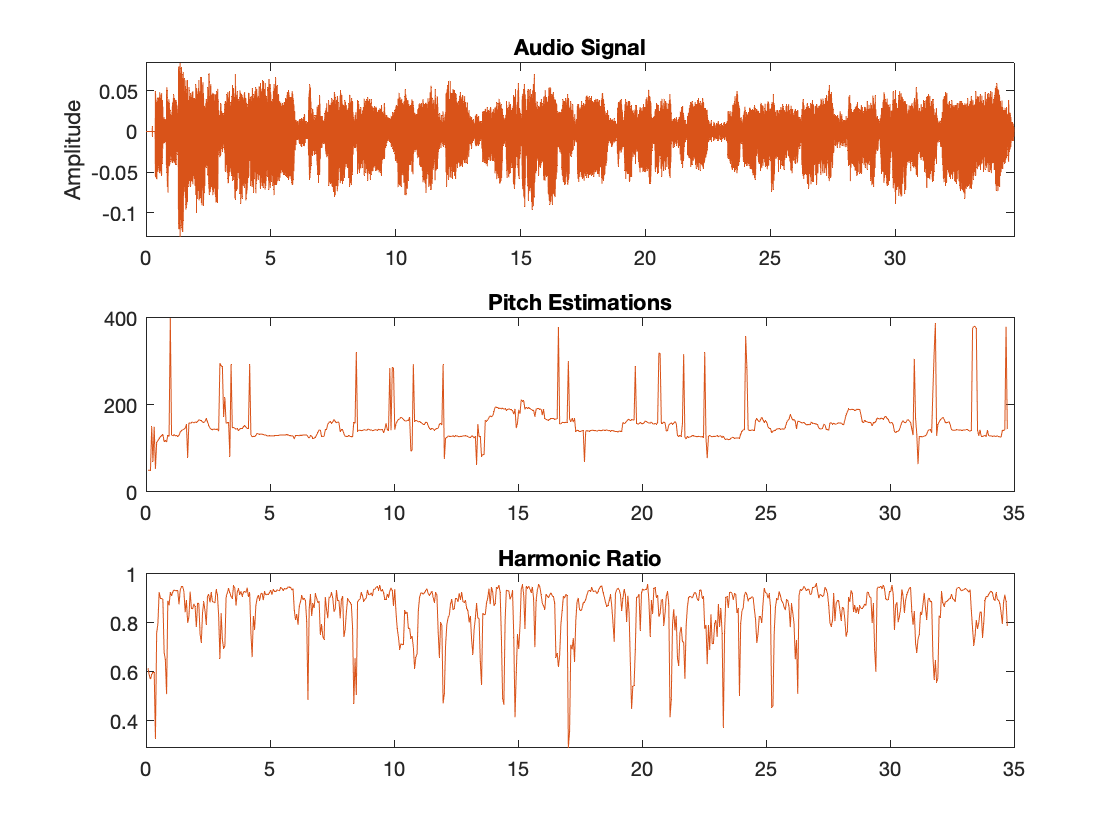

f0 = figure;
tiledlayout(3,1);

nexttile;
t = (0:size(y,1)-1)/Fs;
plot(t,y);
ylabel("Amplitude");
title("Audio Signal");
axis tight;

nexttile;
answ = pitch(y,Fs,Method="SRH",WindowLength=winLength,OverlapLength=overlapLength);
t = loc/Fs;
plot(t,answ);
title("Pitch Estimations");
xlabel("");
nexttile;
answ = harmonicRatio(y,Fs,Window=hamming(winLength,"periodic"),OverlapLength=overlapLength);
plot(t,answ);
title("Harmonic Ratio");

new_HZ1 = zeros(120,1);
l= length(HZmanual);

for i=1:l
    k = 2*i - 1;
    new_HZ1(k)=HZmanual(i);
end

l= length(new_HZ1);
for i=1:l
    if new_HZ1(i) ~= 0

    else
    r = log((new_HZ1(i-1))/16.3515978312876);
    r = r/(log(2));
    r = r*1200;
    j = r+50;
    j = j* (log(2));
    j = j/1200;
    j = j+log(16.3515978312876);
    r = exp(j);
    new_HZ1(i)= r;
    end
end

TEMPORARY = F0;

diff_f0 = diff(F0(:,1));
l=length(diff_f0);

count = 0;
j=0;
for i=1:l
    if diff_f0(i)~=0
        count = count + 1;
    else
        if count==0
        else
            for k=0:count-2
                F0(k+i-count+1,1)=F0(i-count,1);
            end
        end
        count = 0;
    end
end

min =1000;
for i = 1:l+1
    for k=1: 120
        if (abs(new_HZ1(k)-F0(i)) < min)
            min = abs(new_HZ1(k)-F0(i,1));
            min_index = k;
        end
    end
    Matching(min_index) = Matching(min_index)+ 1;
    min = 1000;
end 
Matching(1)=0;


MATCHING RATES ARE:
Rast Matching Rate = 50.000000 
Ajam Matching Rate = 57.925072 
Nahawand Matching Rate = 46.685879 
Bayat Matching Rate = 31.556196 
Kurd Matching Rate = 28.242075 
Hijaz Matching Rate = 25.072046 
Saba Matching Rate = 28.674352 
Sekah Matching Rate = 12.824207

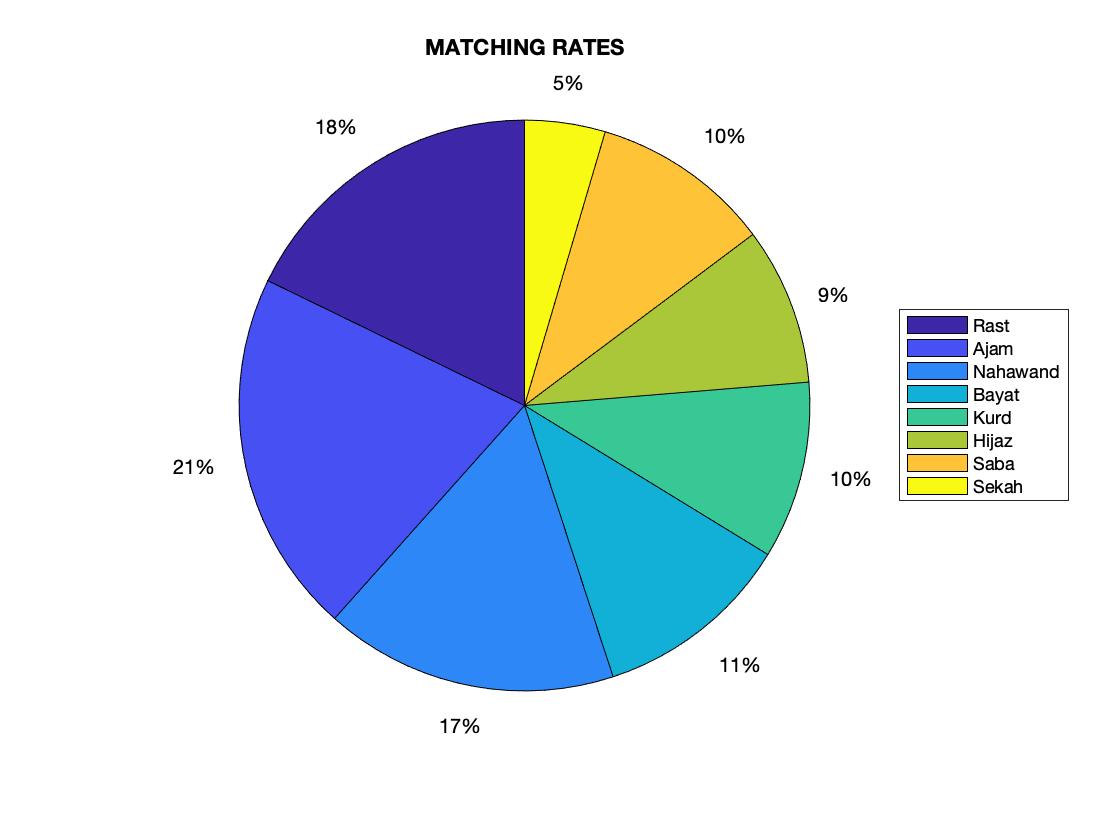

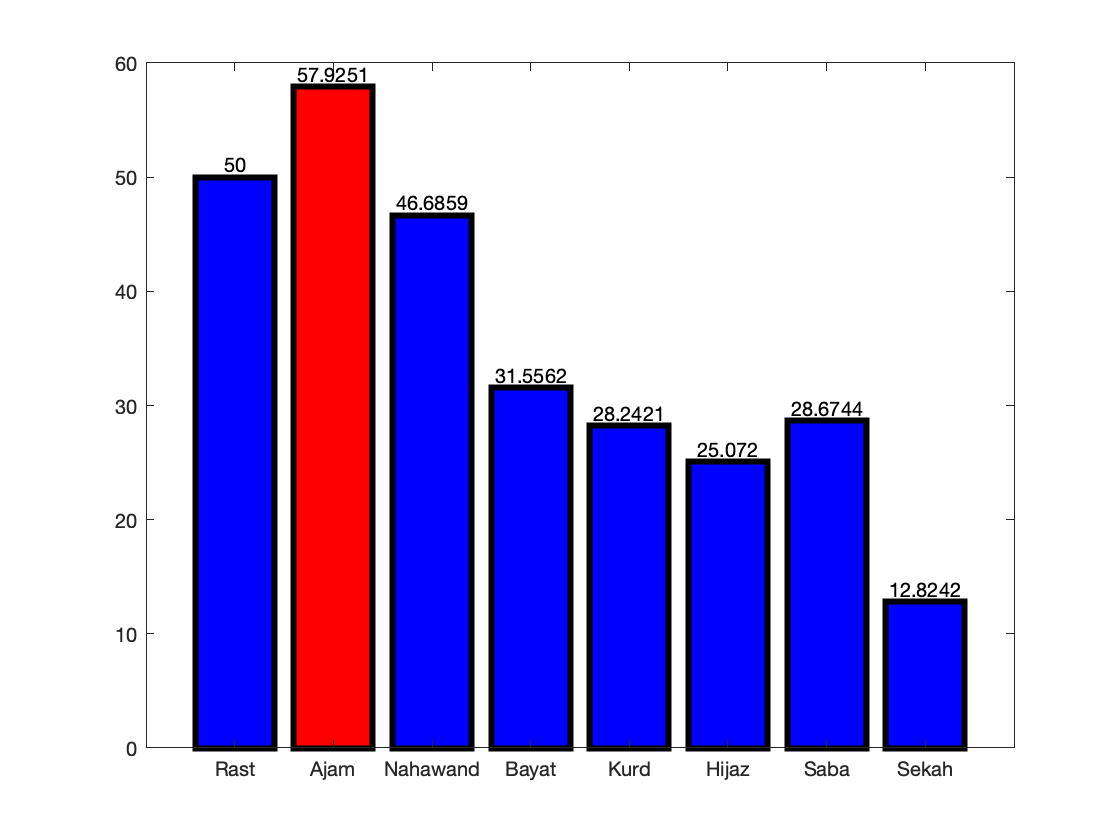

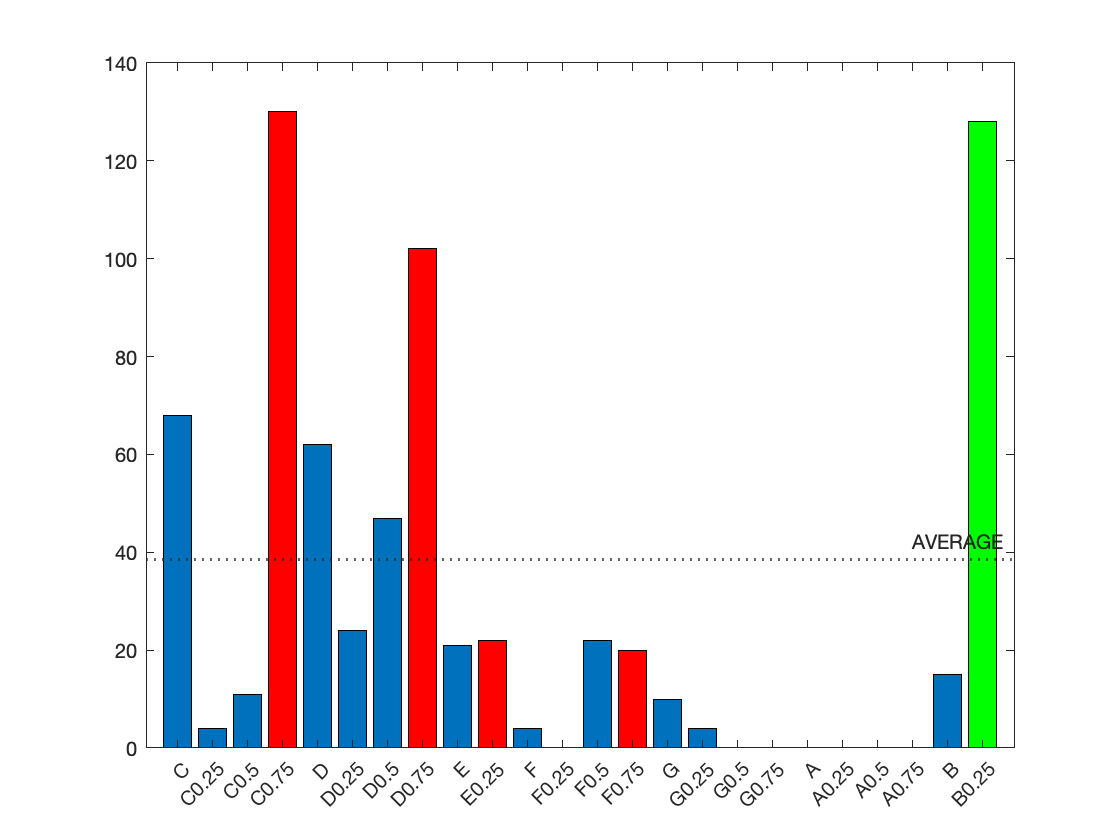

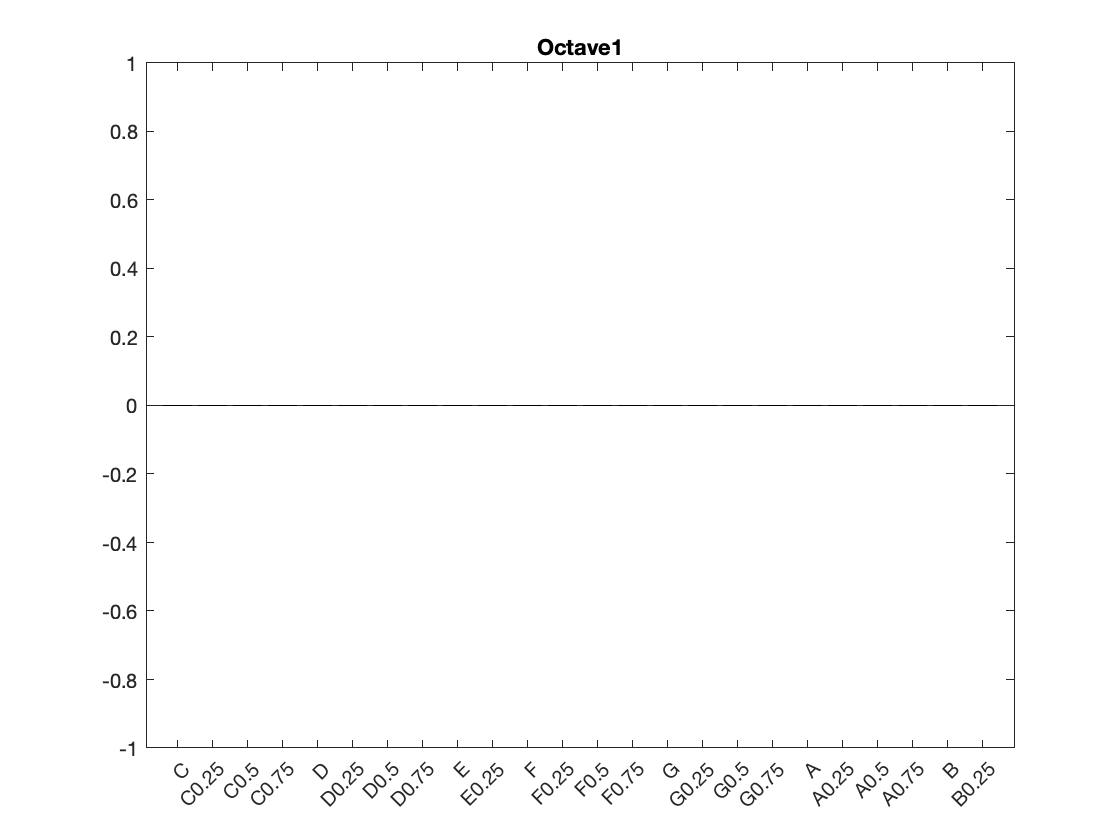

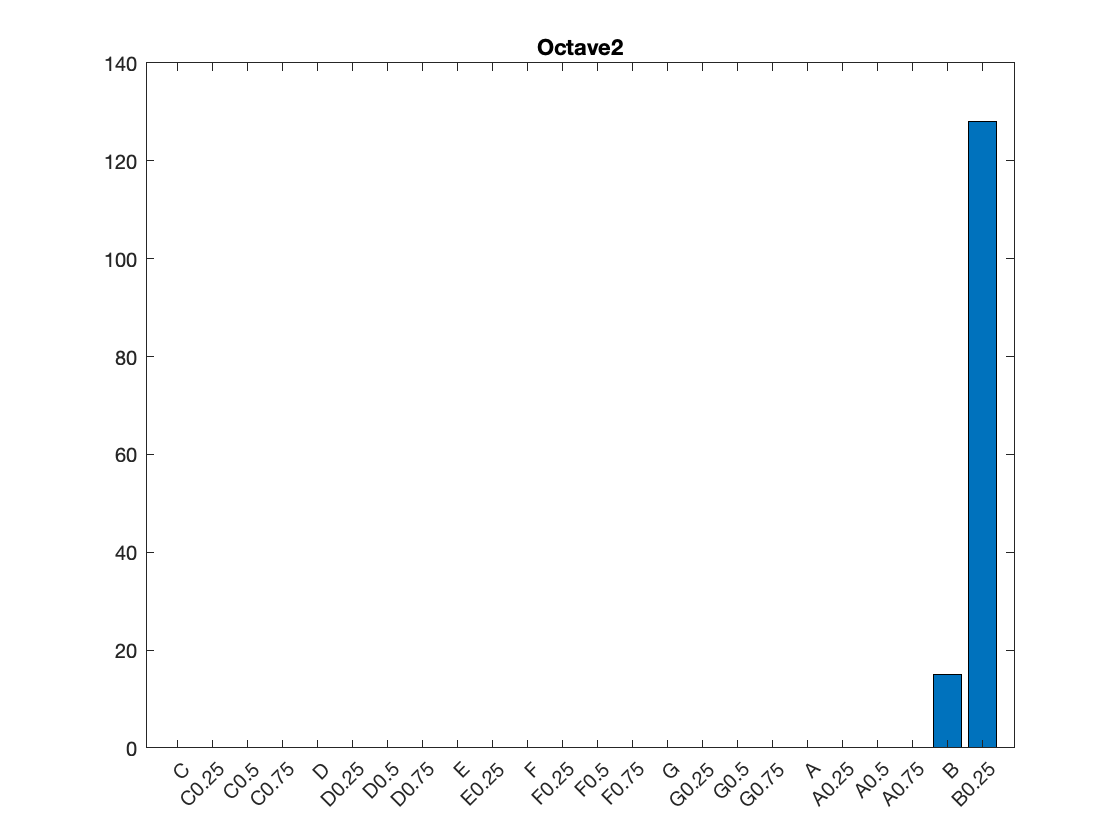

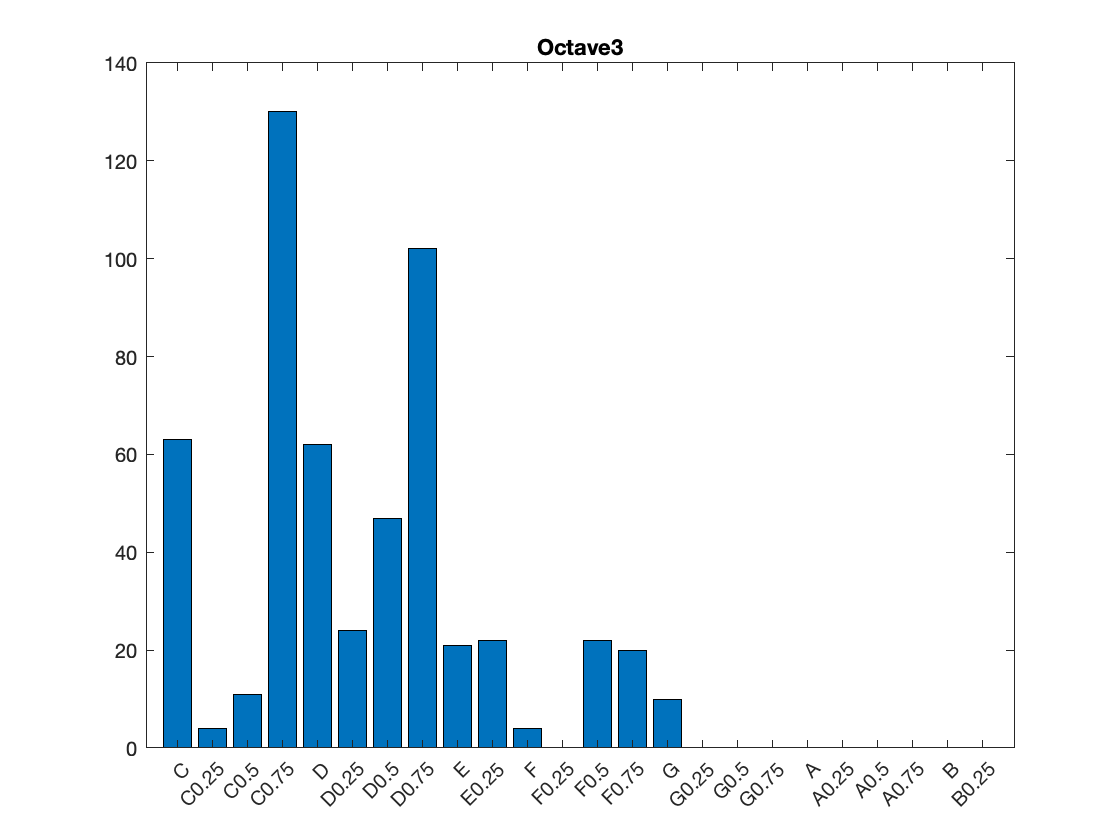

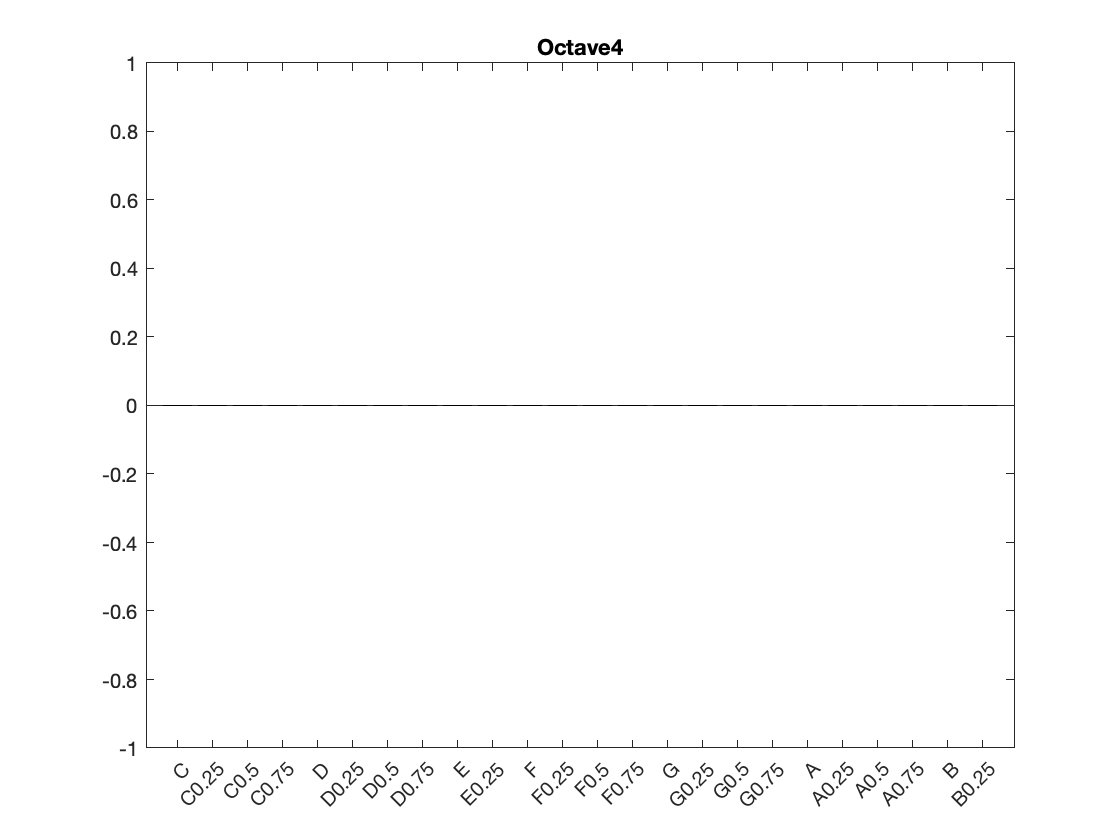

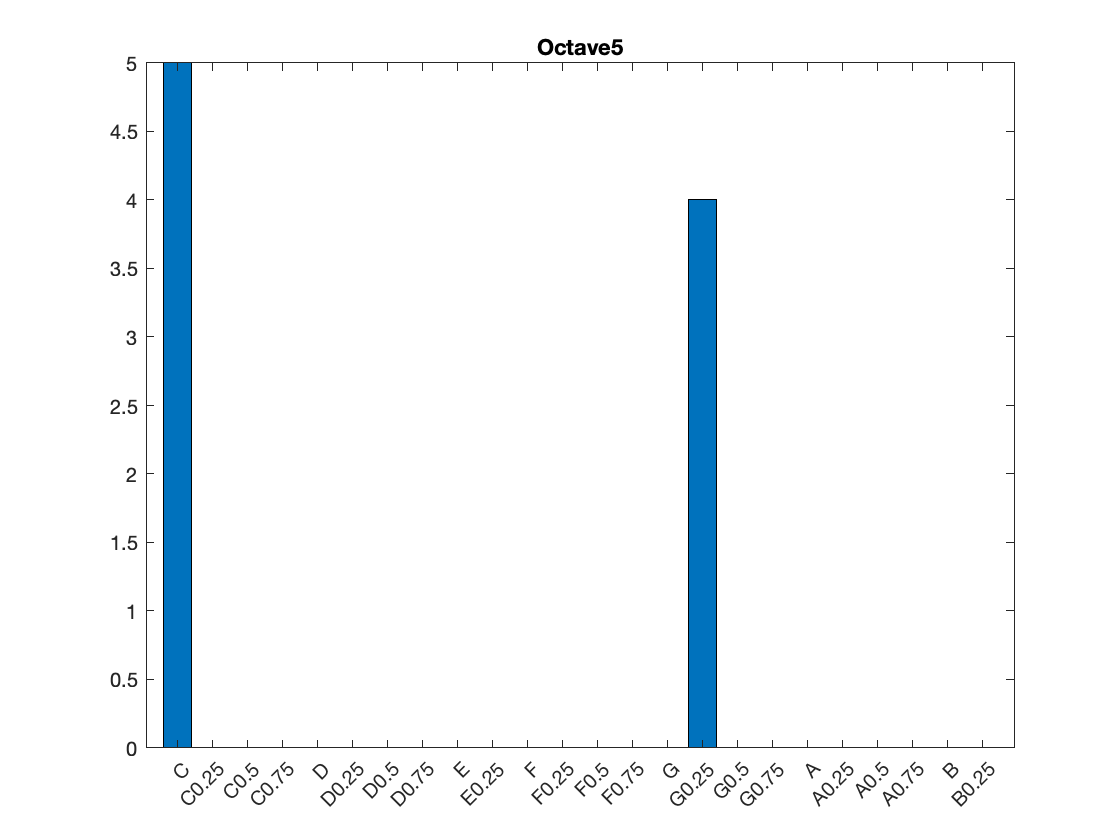

    MATCH = zeros(120,1);
    sum = 0;
    count = 0;
    for i = 1:120
        MATCH(i)=Matching(i);
        sum = MATCH(i) + sum;
        if(MATCH(i)>0)
            count = count + 1;
        end
    end 
    
    avg = sum/count;
    avg = avg + Deviation;


if Filtering == 1
    sum=0;
    count=0;
    MATCH = zeros(120,1)
    for i = 1:120
        MATCH(i)=Matching(i);
        sum = MATCH(i) + sum;
        if(MATCH(i)>0)
            count = count + 1;
        end
    end 

    avg = sum/count;
    avg = avg + Deviation;

    for i = 1:120
        if MATCH(i)<avg 
            MATCH(i)=0;
        elseif MATCH(i)>avg
            MATCH(i)=1;
        end
    end 
    [MAQAM , i] = Maqam_detect(MATCH,BASIC);
elseif Filtering == 0
    Match2 = zeros(120,1);
    for i=1:120
        if Matching(i)>0
            Match2(i)=1;
        end
    end
    [MAQAM , i] = Maqam_detect(Match2,BASIC);
elseif Filtering == 2
    Match = Normal_Filter(Matching,Deviation);
    diff_Filter = diff(Match);
    for i=1:119
        if diff_Filter(i)~=0 || (Match(i+1)>avg && Match(i)>avg)
            if Match(i+1)>Match(i)
                Match(i)=0;
            else
                Match(i+1)=0;
            end
        end
    end
    Match3 = zeros(120,1);
    for i=1:120
        if Match(i)>0
            Match3(i)=1;
        end
    end
    [MAQAM , i] = Maqam_detect(Match3,BASIC);
end
if analysation
    MAQAM_ANALYSATION(Matching,MAQAM,i);
end

disp(MAQAM);2

AJAM


ans = 2

## Maqam detect function calling

## 1-KURD 2-HIJAZ 3-NAHAWAND 4-AJAM 5-SEKAH 6-RAST 7-BAYAT 8-SABA

function [MAQAM,i] = Maqam_detect(Matching,BASIC)
    % find first 1 in matching array
    length = 120;
    %
    if BASIC == 0
        for i=1:length
            if (Matching(i)==1)
                % find second 1 in matching array
                for k=i+1:length
                    if Matching(k)==1
                        % determine what is the distance between two 1 to split
                        % the maqams to better analysation
                        % if the distance is 1 so we will search for kurd or
                        % hijaz
                        % if the distance is 2 so we will search for nahawand
                        % or ajam
                        if k == i+2
                            for s=k+1:length
                                % find 3rd 1
                                if Matching(s) == 1
                                    if s == k+4
                                        % distance is 1-2 so KURD
                                        MAQAM = "KURD";
                                        return
                                    elseif s == k+6
                                        % distance is 1-3 so HIJAZ
                                        MAQAM = "HIJAZ";
                                        return
                                    end
                                end
                            end
                        elseif k == i+4
                            for s=k+1:length
                                if Matching(s) == 1
                                    if s== k+2
                                        % distance is 2-1 so NAHAWAND
                                        MAQAM = "NAHAWAND";
                                        return
                                    elseif s== k+4
                                        % distance is 2-2 so AJAM
                                        MAQAM = "AJAM";
                                        return
                                    elseif s == k+3
                                        MAQAM = "RAST";
                                        return
                                    end
                                end
                            end
                        elseif k == i+3
                            for s=k+1:length
                                if Matching(s) == 1
                                    if s == k+4
                                        MAQAM = "SEKAH";
                                        return
                                    elseif s == k+3
                                        for n=s+1:length
                                            if Matching(n) == 1
                                                if n == s+4
                                                    MAQAM = "BAYAT";
                                                    return
                                                elseif n == s+2
                                                    MAQAM = "SABA";
                                                    return
                                                end
                                            end
                                        end
                                    end
                                end
                            end
                            
                        end
                    end
                end
            end
        end
                   
    elseif BASIC > 0
        i=BASIC;
            if (Matching(i)==1)
                % find second 1 in matching array
                for k=i+1:length
                    if Matching(k)==1
                        % determine what is the distance between two 1 to split
                        % the maqams to better analysation
                        % if the distance is 1 so we will search for kurd or
                        % hijaz
                        % if the distance is 2 so we will search for nahawand
                        % or ajam
                        if k == i+2
                            for s=k+1:length
                                % find 3rd 1
                                if Matching(s) == 1
                                    if s == k+4
                                        % distance is 1-2 so KURD
                                        MAQAM = "KURD";
                                        return
                                    elseif s == k+6
                                        % distance is 1-3 so HIJAZ
                                        MAQAM = "HIJAZ";
                                        return
                                    end
                                end
                            end
                        elseif k == i+4
                            for s=k+1:length
                                if Matching(s) == 1
                                    if s== k+2
                                        % distance is 2-1 so NAHAWAND
                                        MAQAM = "NAHAWAND";
                                        return
                                    elseif s== k+4
                                        % distance is 2-2 so AJAM
                                        MAQAM = "AJAM";
                                        return
                                    elseif s == k+3
                                        MAQAM = "RAST";
                                        return
                                    end
                                end
                            end
                        elseif k == i+3
                            for s=k+1:length
                                if Matching(s) == 1
                                    if s == k+4
                                        MAQAM = "SEKAH";
                                        return
                                    elseif s == k+3
                                        for n=s+1:length
                                            if Matching(n) == 1
                                                if n == s+4
                                                    MAQAM = "BAYAT";
                                                    return
                                                elseif n == s+2
                                                    MAQAM = "SABA";
                                                    return
                                                end
                                            end
                                        end
                                    end
                                end
                            end
                            
                        end
                    end
                end
            end
    end
    MAQAM="ERROR";
    return
end

function [MATCH] = Normal_Filter(Match,Deviation)
    sum=0;
    count=0;
    MATCH = zeros(120,1);
    for i = 1:120
        MATCH(i)=Match(i);
        sum = MATCH(i) + sum;
        if(MATCH(i)>0)
            count = count + 1;
        end
    end 

    avg = sum/count;
    avg = avg + Deviation - 1;
    for i = 1:120
        if MATCH(i)<avg 
            MATCH(i)=0;
        end
    end 
    return
end

function [ERTEQAZ] = ERTEQAZ_DETECTOR(new_HZ1,Matching,method,range,winLength,overlapLength,overlapDur,medFiltLength,winDur,Fs1,y1) %#ok<INUSL> 
    winLength = round(winDur*Fs1);
    overlapLength = round(overlapDur*Fs1);
    [F1,~] = pitch(y1,Fs1, ...
        'Method',method, ...
        'Range',range, ...
        'WindowLength',winLength, ...
        'OverlapLength',overlapLength, ...
        "MedianFilterLength",medFiltLength);


    l=length(F1);

    min =1000;
    for i = 1:l
        for k=1: 120
            if (abs(new_HZ1(k)-F1(i)) < min)
                min = abs(new_HZ1(k)-F1(i,1));
                min_index = k;
            end
        end
        Matching(min_index) = Matching(min_index)+ 1;
        min = 1000;
    end 
    Matching(1)=0;
    max = 0;
    ERTEQAZ = 0;
    for i=1:120
        if(Matching(i)>max)
            max =Matching(i);
            ERTEQAZ = i;
        end
    end
    return
end
function [] = MAQAM_ANALYSATION(Matching,MAQAM,ER)
    global HIJAZ;
    global RAST;
    global BAYAT; %#ok<*GVMIS> 
    global NAHAWAND;
    global SEKAH;
    global AJAM;
    global SABA;
    global KURD;
    global avg;
    count = 0;
    if MAQAM == "RAST"
        k=1;
    elseif MAQAM == "AJAM"
        k=2;
    elseif MAQAM == "NAHAWAND"
        k=3;
    elseif MAQAM == "BAYAT"
        k=4;
    elseif MAQAM == "KURD"
        k=5;
    elseif MAQAM == "HIJAZ"
        k=6;
    elseif MAQAM == "SABA"
        k=7;
    elseif MAQAM == "SEKAH"
        k=8;
    end
    for i=1: length(Matching)
        count = count + Matching(i);
    end
    if MAQAM == "RAST" || MAQAM == "AJAM" || MAQAM == "NAHAWAND"
        ra_pr = Matching_Rate(ER,"RAST",count,Matching);
        aj_pr = Matching_Rate(ER,"AJAM",count,Matching);
        na_pr = Matching_Rate(ER,"NAHAWAND",count,Matching);
        by_pr = Matching_Rate(ER+4,"BAYAT",count,Matching);
        ku_pr = Matching_Rate(ER+4,"KURD",count,Matching);
        hi_pr = Matching_Rate(ER+4,"HIJAZ",count,Matching);
        sa_pr = Matching_Rate(ER+4,"SABA",count,Matching);
        se_pr = Matching_Rate(ER+7,"SEKAH",count,Matching);
    elseif MAQAM == "BAYAT" || MAQAM == "KURD" || MAQAM == "HIJAZ" || MAQAM == "SABA"
        ra_pr = Matching_Rate(ER-4,"RAST",count,Matching);
        aj_pr = Matching_Rate(ER-4,"AJAM",count,Matching);
        na_pr = Matching_Rate(ER-4,"NAHAWAND",count,Matching);
        by_pr = Matching_Rate(ER,"BAYAT",count,Matching);
        ku_pr = Matching_Rate(ER,"KURD",count,Matching);
        hi_pr = Matching_Rate(ER,"HIJAZ",count,Matching);
        sa_pr = Matching_Rate(ER,"SABA",count,Matching);
        se_pr = Matching_Rate(ER+3,"SEKAH",count,Matching);
    elseif MAQAM == "SEKAH"
        ra_pr = Matching_Rate(ER-7,"RAST",count,Matching);
        aj_pr = Matching_Rate(ER-3,"AJAM",count,Matching);
        na_pr = Matching_Rate(ER-3,"NAHAWAND",count,Matching);
        by_pr = Matching_Rate(ER-3,"BAYAT",count,Matching);
        ku_pr = Matching_Rate(ER-3,"KURD",count,Matching);
        hi_pr = Matching_Rate(ER-3,"HIJAZ",count,Matching);
        sa_pr = Matching_Rate(ER-3,"SABA",count,Matching);
        se_pr = Matching_Rate(ER,"SEKAH",count,Matching);
    else 
        return
    end
    fprintf("MATCHING RATES ARE:\n");
    fprintf("Rast Matching Rate = %f \n", ra_pr);
    fprintf("Ajam Matching Rate = %f \n", aj_pr);
    fprintf("Nahawand Matching Rate = %f \n", na_pr);
    fprintf("Bayat Matching Rate = %f \n", by_pr);
    fprintf("Kurd Matching Rate = %f \n", ku_pr);
    fprintf("Hijaz Matching Rate = %f \n", hi_pr);
    fprintf("Saba Matching Rate = %f \n", sa_pr);
    fprintf("Sekah Matching Rate = %f",se_pr);



    f1 = figure; %#ok<NASGU> 
    y2011 = [ra_pr,aj_pr,na_pr,by_pr,ku_pr,hi_pr,sa_pr,se_pr];
    labels = {'Rast','Ajam','Nahawand','Bayat','Kurd','Hijaz','Saba','Sekah'};
    ax2 = nexttile;
    pie(ax2,y2011);
    title('MATCHING RATES');
    lgd = legend(labels);
    lgd.Layout.Tile = 'east';

    f2 = figure; %#ok<NASGU> 
    X = categorical({'Rast','Ajam','Nahawand','Bayat','Kurd','Hijaz','Saba','Sekah'});
    X = reordercats(X,{'Rast','Ajam','Nahawand','Bayat','Kurd','Hijaz','Saba','Sekah'});
    Y = [ra_pr ; aj_pr ; na_pr ; by_pr ; ku_pr ; hi_pr ; sa_pr ; se_pr];
    %b = bar(X,Y,'stacked');
    b = bar(X,Y,'FaceColor',[0 0 1],'EdgeColor',[0 0 0],'LineWidth',3);
    b.FaceColor = 'flat';
    b.CData(k,:) = [1 0 0];
    xtips2 = b(1).XEndPoints;
    ytips2 = b(1).YEndPoints;
    labels2 = string(b(1).YData);
    text(xtips2,ytips2,labels2,'HorizontalAlignment','center',...
        'VerticalAlignment','bottom')       



    f3 = figure; %#ok<NASGU> 
    X = categorical({'C','C0.25','C0.5','C0.75','D','D0.25','D0.5','D0.75','E','E0.25','F','F0.25','F0.5','F0.75','G','G0.25','G0.5','G0.75','A','A0.25','A0.5','A0.75','B','B0.25'});
    X = reordercats(X,{'C','C0.25','C0.5','C0.75','D','D0.25','D0.5','D0.75','E','E0.25','F','F0.25','F0.5','F0.75','G','G0.25','G0.5','G0.75','A','A0.25','A0.5','A0.75','B','B0.25'});
    Notes = zeros(24,1);
    for i=1:120
        k = mod(i-1,24) + 1;
        Notes(k) = Notes(k) + Matching(i);
    end
    
    bb = bar(X,Notes,'stacked');
    bb.FaceColor = 'flat';
    
    %yline(avg);
    yline(avg,':','AVERAGE','LineWidth',1.5);

    ER = mod(ER-1,24) + 1;
    if MAQAM == "RAST"
        for i=1:7
            l = RAST(i) + ER;
            l = mod(l-1,24) + 1;
            if i == 1
                bb.CData(l,:) = [0 1 0];
            else
            bb.CData(l,:) = [1 0 0]; 
            end
        end
    elseif MAQAM == "AJAM"
        for i=1:7
            l = AJAM(i) + ER;
            l = mod(l-1,24) + 1;
            if i == 1
                bb.CData(l,:) = [0 1 0];
            else
            bb.CData(l,:) = [1 0 0]; 
            end
        end
    elseif MAQAM == "NAHAWAND"
        for i=1:8
            l = NAHAWAND(i) + ER;
            l = mod(l-1,24) + 1;
            if i == 1
                bb.CData(l,:) = [0 1 0];
            else
            bb.CData(l,:) = [1 0 0]; 
            end
        end
    elseif MAQAM == "BAYAT"
        for i=1:7
            l = BAYAT(i) + ER;
            l = mod(l-1,24) + 1;
            if i == 1
                bb.CData(l,:) = [0 1 0];
            else
            bb.CData(l,:) = [1 0 0]; 
            end
        end
    elseif MAQAM == "KURD"
        for i=1:7
            l = KURD(i) + ER;
            l = mod(l-1,24) + 1;
            if i == 1
                bb.CData(l,:) = [0 1 0];
            else
            bb.CData(l,:) = [1 0 0]; 
            end 
        end
    elseif MAQAM == "HIJAZ"
        for i=1:7
            l = HIJAZ(i) + ER;
            l = mod(l-1,24) + 1;
            if i == 1
                bb.CData(l,:) = [0 1 0];
            else
            bb.CData(l,:) = [1 0 0]; 
            end  
        end
    elseif MAQAM == "SABA"
        for i=1:7
            l = SABA(i) + ER;
            l = mod(l-1,24) + 1;
            if i == 1
                bb.CData(l,:) = [0 1 0];
            else
            bb.CData(l,:) = [1 0 0]; 
            end 
        end
    elseif MAQAM == "SEKAH"    
        for i=1:7
            l = SEKAH(i) + ER;
            l = mod(l-1,24) + 1;
            if i == 1
                bb.CData(l,:) = [0 1 0];
            else
            bb.CData(l,:) = [1 0 0]; 
            end  
        end
    end

    Octave = zeros(24,1);
    for i=1:120
        k = mod(i-1,24) + 1;
        Octave(k) = Octave(k) + Matching(i);
        if (mod(i,24)==0)
            figure;
            nexttile;
            X = categorical({'C','C0.25','C0.5','C0.75','D','D0.25','D0.5','D0.75','E','E0.25','F','F0.25','F0.5','F0.75','G','G0.25','G0.5','G0.75','A','A0.25','A0.5','A0.75','B','B0.25'});
            X = reordercats(X,{'C','C0.25','C0.5','C0.75','D','D0.25','D0.5','D0.75','E','E0.25','F','F0.25','F0.5','F0.75','G','G0.25','G0.5','G0.75','A','A0.25','A0.5','A0.75','B','B0.25'});
            bar(X,Octave,'stacked');
            chr = int2str(floor((i-1)/24) + 1);
            tt = "Octave" + chr;
            title(tt);
            Octave = zeros(24,1);
        end
    end

end
function [percent] = Matching_Rate(ER,MAQAMM,count,Matching)
    keys = 0;
    i = ER;
    if MAQAMM == "RAST"
        keys = keys + Matching(i);
        keys = keys + Matching(i+4);
        keys = keys + Matching(i+7);
        keys = keys + Matching(i+10);
        keys = keys + Matching(i+14);
        keys = keys + Matching(i+18);
        keys = keys + Matching(i+21);
        keys = keys + Matching(i+24);
        percent = keys/count * 100;
        return
    elseif MAQAMM == "AJAM"
        keys = keys + Matching(i);
        keys = keys + Matching(i+4);
        keys = keys + Matching(i+8);
        keys = keys + Matching(i+10);
        keys = keys + Matching(i+14);
        keys = keys + Matching(i+18);
        keys = keys + Matching(i+22);
        keys = keys + Matching(i+24);
        percent = keys/count * 100;
        return
    elseif MAQAMM == "NAHAWAND"
        keys = keys + Matching(i);
        keys = keys + Matching(i+4);
        keys = keys + Matching(i+6);
        keys = keys + Matching(i+10);
        keys = keys + Matching(i+14);
        keys = keys + Matching(i+18);
        keys = keys + Matching(i+20);
        keys = keys + Matching(i+24);
        percent = keys/count * 100;
        return
    elseif MAQAMM == "BAYAT"
        keys = keys + Matching(i);
        keys = keys + Matching(i+3);
        keys = keys + Matching(i+6);
        keys = keys + Matching(i+10);
        keys = keys + Matching(i+14);
        keys = keys + Matching(i+18);
        keys = keys + Matching(i+21);
        keys = keys + Matching(i+24);
        percent = keys/count * 100;
        return
    elseif MAQAMM == "KURD"
        keys = keys + Matching(i);
        keys = keys + Matching(i+2);
        keys = keys + Matching(i+6);
        keys = keys + Matching(i+10);
        keys = keys + Matching(i+14);
        keys = keys + Matching(i+16);
        keys = keys + Matching(i+20);
        keys = keys + Matching(i+24);
        percent = keys/count * 100;
        return
    elseif MAQAMM == "HIJAZ"
        keys = keys + Matching(i);
        keys = keys + Matching(i+2);
        keys = keys + Matching(i+8);
        keys = keys + Matching(i+10);
        keys = keys + Matching(i+14);
        keys = keys + Matching(i+16);
        keys = keys + Matching(i+20);
        keys = keys + Matching(i+24);
        percent = keys/count * 100;
        return
    elseif MAQAMM == "SABA"
        keys = keys + Matching(i);
        keys = keys + Matching(i+3);
        keys = keys + Matching(i+6);
        keys = keys + Matching(i+8);
        keys = keys + Matching(i+14);
        keys = keys + Matching(i+16);
        keys = keys + Matching(i+20);
        keys = keys + Matching(i+24);
        percent = keys/count * 100;
        return
    elseif MAQAMM == "SEKAH"
        keys = keys + Matching(i);
        keys = keys + Matching(i+3);
        keys = keys + Matching(i+7);
        keys = keys + Matching(i+9);
        keys = keys + Matching(i+15);
        keys = keys + Matching(i+17);
        keys = keys + Matching(i+21);
        keys = keys + Matching(i+24);
        percent = keys/count * 100;
        return
    end
end

*Copyright 2022 Faisal Omari, Inc. *